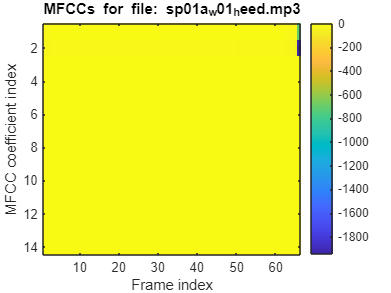

% Define the speaker numbers and words
speakers = 1:30;
words = {'heed', 'hid', 'head', 'had', 'hard', 'hud', 'hod', 'hoard', 'hood', 'whod', 'heard'};

% Generate the audio file list using loops
audio_files = cell(1, length(speakers) * length(words));  % Preallocate cell array
index = 1;  % Initialize index for the audio_files array

for speaker = speakers
    for word_idx = 1:length(words)
        % Create the filename for each combination of speaker and word
        audio_files{index} = sprintf('sp%02da_w%02d_%s.mp3', speaker, word_idx, words{word_idx});
        index = index + 1;  % Increment the index
    end
end


% Initialise variables to store MFCCs
num_files = length(audio_files);
mfccs = cell(num_files, 1);  % Cell array to hold the MFCCs for each audio file

% PARAMETERS
frame_length_ms = 30;   % Frame length in ms
hop_size_ms = 10;       % Hop size in ms
num_mfcc_coeffs = 13;   % Number of MFCC coefficients (including zeroth)

% Assuming the sampling rate is the same for all files, we read the first file to get fs
[example_audio, fs_example] = audioread(audio_files{1});

% Frame size and hop size in samples
frame_length_samples = round(frame_length_ms / 1000 * fs_example);  % Convert ms to samples
hop_size_samples = round(hop_size_ms / 1000 * fs_example);        % Convert ms to samples

% Define a function for extracting MFCCs from a windowed frame
extract_mfcc_from_frame = @(audio, fs, frame_length, hop_size, num_coeffs) ...
    mfcc(audio, fs, 'Window', hamming(frame_length, 'periodic'), ...
         'OverlapLength', frame_length - hop_size, 'NumCoeffs', num_coeffs);

% Loop through the audio files and extract MFCCs for each one
for i = 1:num_files
    [audio_data, fs] = audioread(audio_files{i});  % Read the current audio file
    mfccs{i} = extract_mfcc_from_frame(audio_data, fs, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
end

% Now 'mfccs' contains the MFCC features for each audio file

% Choose the file you want to display the MFCC for
file_index = 1;  % Change this to select a different file

% Extract the MFCCs for the selected file
mfcc_data = mfccs{file_index};

% PLOT MFCCs SPECTOGRAM-LIKE IMAGE
figure;
imagesc(mfcc_data');  % Transpose to make time on x-axis and MFCC coefficients on y-axis
colorbar;  % Display color bar to represent the magnitude of the MFCCs
xlabel('Frame index');
ylabel('MFCC coefficient index');
title(sprintf('MFCCs for file: %s', audio_files{file_index}));
axis tight;  % Adjust axis limits to fit the data (adjust axis for better readability)

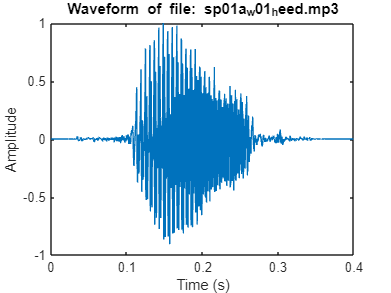


%PLOT THE AUDIO WAVEFORM
figure;
plot((1:length(audio_data))/fs, audio_data);  % Time vs. amplitude plot
xlabel('Time (s)');
ylabel('Amplitude');
title(sprintf('Waveform of file: %s', audio_files{file_index}));

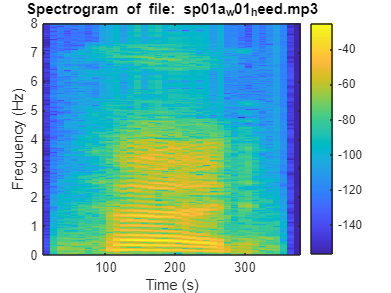


%PLOT THE SPECTOGRAM OF THE AUDIO SIGNAL
figure;
spectrogram(audio_data, hamming(frame_length_samples), frame_length_samples - hop_size_samples, 1024, fs, 'yaxis');
title(sprintf('Spectrogram of file: %s', audio_files{file_index}));
colorbar;
ylabel('Frequency (Hz)');
xlabel('Time (s)');

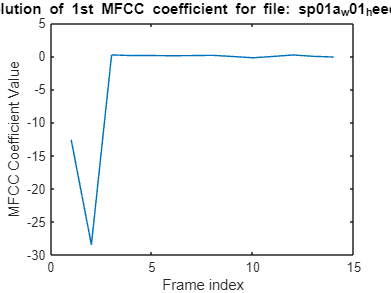


%%MFCC COFFICENT EVOLUTION OVER TIME
figure;
plot(1:size(mfcc_data, 2), mfcc_data(1, :));  % Plot the 1st MFCC coefficient over time
xlabel('Frame index');
ylabel('MFCC Coefficient Value');
title(sprintf('Evolution of 1st MFCC coefficient for file: %s', audio_files{file_index}));

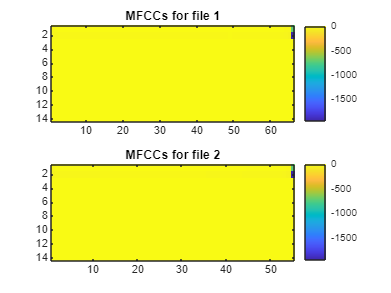


%%COMPARISON OF MFFC FOR MULTIPLE FILES
figure;
subplot(2,1,1);  % First subplot for file 1
imagesc(mfccs{1}');
title('MFCCs for file 1');
colorbar;

subplot(2,1,2);  % Second subplot for file 2
imagesc(mfccs{2}');
title('MFCCs for file 2');
colorbar;

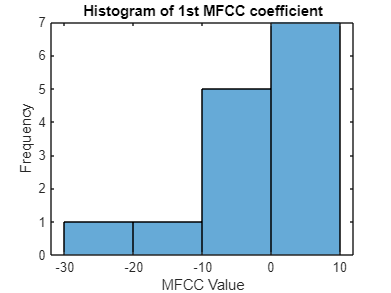


%HISTOGRAM OF MFCC COEFFICENTS
figure;
histogram(mfcc_data(1, :));  % Histogram of the 1st MFCC coefficient
xlabel('MFCC Value');
ylabel('Frequency');
title('Histogram of 1st MFCC coefficient');

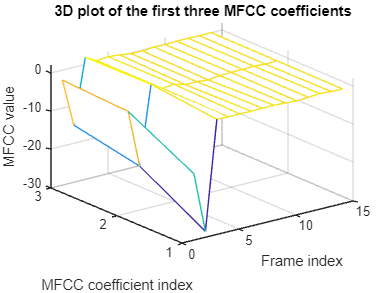


%%3D PLOT OF MFCC FEATURES
figure;
mesh(1:size(mfcc_data, 2), 1:3, mfcc_data(1:3, :));  % Plot 3 first MFCC coefficients
xlabel('Frame index');
ylabel('MFCC coefficient index');
zlabel('MFCC value');
title('3D plot of the first three MFCC coefficients');